# Ray-tracing Based Mobile Wireless Channel Simulator Demo 

## Mobile Scenario Example - NU campus LTE small cell and WIFI coexistence 

Author: Miead Tehrani-Moayyed

Institute for the Wireless Internet of Things, 

Northeastern University, Boston MA, 02115, USA

email: tehranimoayyed.m@northeastern.edu

Last revision: 11-Sep-2022

### Scenario configuration

% Parameters Configuration
parameters.origin = [42.34025, -71.08848];              %Wireless environment origin
parameters.osmfile = "NUcampus.osm";                    %Wireless environment 3D Model OSM file
parameters.fc = 5.8e9;                                  %LTE ISM band Center freq. (Hz)
parameters.nodes.names = {'LTE' 'WIFI' 'UE#1' 'UE#2' 'WIFIUE'};  %Nodes names
parameters.nodes.powers = {30, 22, 20, 20, 15};         %Transmit power (dBm)
parameters.nodes.coordinates = {[42.3405645965253,-71.0892925339939],...        %stationary nodes coordinates
                                [42.3398095978303,-71.0884277156665],...
                                [42.341482,-71.086650; 42.341102,-71.087238; 42.339903,-71.090416],...
                                [42.339757,-71.090343; 42.341045,-71.087006; 42.341412,-71.086518]};%Control points for route
parameters.nodes.heights = {17, 17, [1.5, 1.5, 1.5], [1.5, 1.5, 1.5], 1.5};                         %Height of nodes
parameters.nodes.antenna = {'isotropic' 'isotropic' 'isotropic' 'isotropic' 'isotropic'};           %Nodes antenna type
parameters.nodes.antAngle = {0 0 0 0 0};                %Nodes antenna azimuth angles 
parameters.nodes.velocity = {0 0 11.18 5.6 nan};        %Nodes velocity [m/s]
parameters.nodes.mobilityType = {'stationary' 'stationary' 'route' 'route' 'custom'};
parameters.Ts = 1000e-3;                                %Mobile channel sampling interval [s]
parameters.scenarioDuration = 70;                       %Scenario duration [s]
parameters.rt.nReflections = 3;                         %Number of reflections in raytracing
parameters.rt.BuildingsMaterial = "custom";             %Type of buildings material
parameters.rt.BuildingsMaterialPermittivity = 5.31;     %Building material permitivity for custom material
parameters.rt.BuildingsMaterialConductivity = 0.1353;   %Building material conductivity for custom material
parameters.rt.TerrainMaterial = "custom";               %Type of terrain material
parameters.rt.TerrainMaterialPermittivity = 5.31;       %Terrain material permitivity for custom material
parameters.rt.TerrainMaterialConductivity = 0.1353;     %Terrain material conductivity for custom material
parameters.rt.polarization = "H";                       %Polarization
parameters.visualization.flag = 1;                      %Visualization request
parameters.visualization.TxId = 1;                      %TX Index for visualization
parameters.visualization.RxId = 4;                      %RX Index for visualization

% Define the custom mobility pattern - RWP in this case
RWP = load('RWPmobility.mat');
parameters.nodes.coordinates {5} = [RWP.snapshots.lat RWP.snapshots.lon]; 

### Channel simulation process

70 snapshots generated for simulation
Ray-tracing snapshots...
1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27,28,29,30,31,32,33,34,35,36,37,38,39,40,41,42,43,44,45,46,47,48,49,50,51,52,53,54,55,56,57,58,59,60,61,62,63,64,65,66,67,68,69,70,
Elapsed time is 1938.250968 seconds.



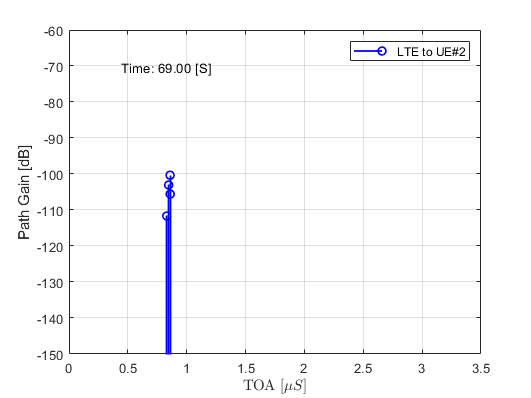

[chMatrix, coordinates, Time] = channelSimulator(parameters);

### Plot time evolution of paths

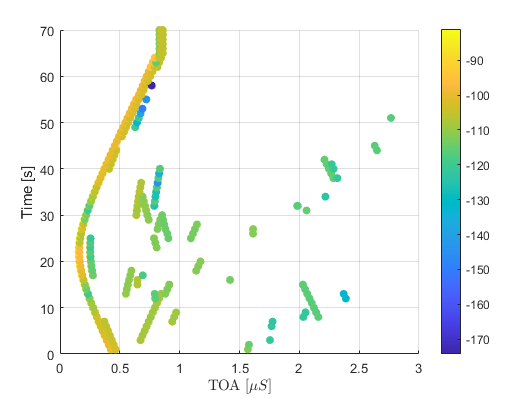

toa_scale_factor = 1e6;

figure
TxID = parameters.visualization.TxId;
RxID = parameters.visualization.RxId;
for snapshotIdx = 1:size(chMatrix,3)
    scatter( chMatrix{TxID,RxID,snapshotIdx}.tau * toa_scale_factor, ...
             ones(size(chMatrix{TxID,RxID,snapshotIdx}.tau)) * parameters.Ts * snapshotIdx, [], ...
             mag2db(abs(chMatrix{TxID,RxID,snapshotIdx}.h)) , 'filled');
    hold on
end
colorbar
grid on
xlabel('TOA [$\mu S$]','Interpreter','latex');
ylabel('Time [s]')

### Visualize CIR for snapshots of channels

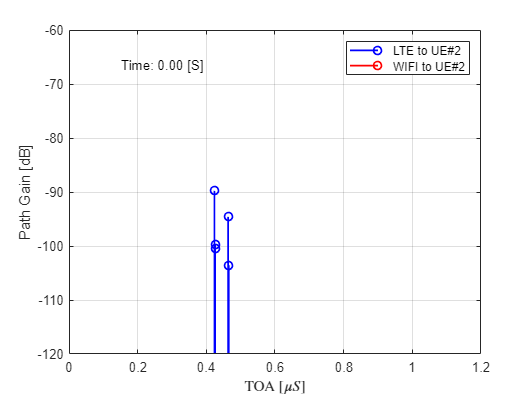

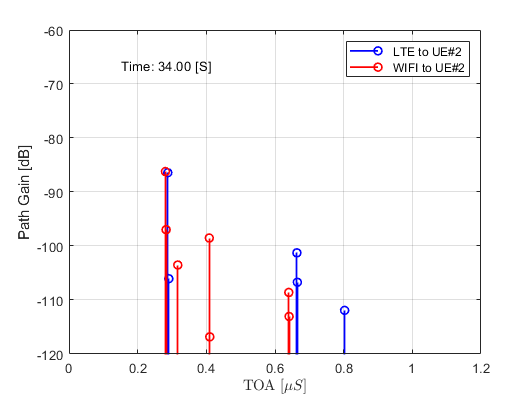

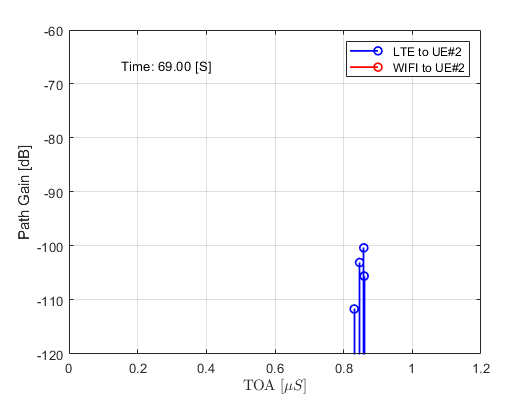

TxID = [1 2];
RxID = 4;
snapshots = [1, 35, 70]; 
toa_scale_factor=1e6;
colors = ['b'; 'r';'g';'m'; 'c'; 'k'; 'b'; 'y'];

for snapshotIdx = 1 : numel(snapshots)
    figure
    legends = strings(1,1);
    legendsIdx = 1;
    for TxIdx = 1 : numel(TxID)
        for RxIdx = 1 : numel(RxID)
            Tx = (TxID(TxIdx));
            Rx = (RxID(RxIdx));

            if size(chMatrix{Tx,Rx,snapshots(snapshotIdx)},1) > 0
                
                    stem((chMatrix{Tx,Rx,snapshots(snapshotIdx)}.tau)*toa_scale_factor, ...
                        mag2db(abs(chMatrix{Tx,Rx,snapshots(snapshotIdx)}.h)),'BaseValue',(-150), ...
                        'Color',colors((TxIdx-1)*numel(RxID)+RxIdx),'LineWidth',1.25);

                    legends(legendsIdx) = sprintf("%s to %s",parameters.nodes.names{Tx},parameters.nodes.names{Rx});
                    legend(legends);
                    legendsIdx = legendsIdx + 1;
              
            else
                stem([],[]);
            end

            hold on
        end
    end

    hold off
    ylim([-120,-60])
    xlim([0,1.2])
    ylabel('Path Gain [dB]');
    xlabel('TOA [$\mu S$]','Interpreter','latex');
    grid on
    text(xlim*[7/8;1/8],ylim*[1/8;7/8]+1,sprintf('Time: %.2f [S]',Time(snapshots(snapshotIdx))*1e-3));

end

### Plot path loss and generate path loss matrix

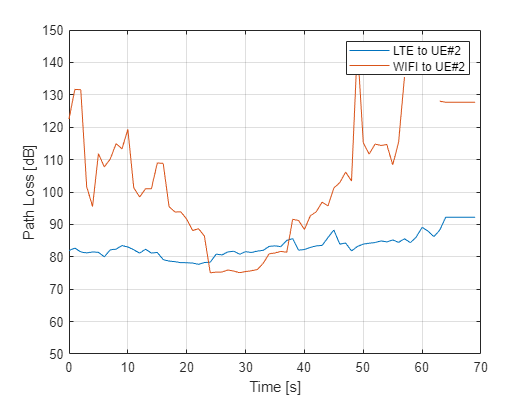

TxID = [1, 2];
RxID = 4;

plMatrix = generatePLmatrix(chMatrix);

% plot Path Loss using plMatrix
figure
legends = strings(numel(TxID)*numel(RxID),1);
for TxIdx = 1 : numel(TxID)

    for RxIdx = 1 : numel(RxID)
        Tx = (TxID(TxIdx));
        Rx = (RxID(RxIdx));

        PL = plMatrix(Tx,Rx,:);

        plot(Time/1000,PL(:));
        hold on
        legends((TxIdx-1)*numel(RxID)+RxIdx) = sprintf("%s to %s",parameters.nodes.names{Tx},parameters.nodes.names{Rx});

    end

end
legend(legends);
ylabel("Path Loss [dB]");
xlabel("Time [s]");
grid on;
ylim([50,150])

## Channel taps approximation

Approximate the channels to the four taps for emulation on Colosseum

[chMatrix_hat, plMatrix_hat] = chApproximation(chMatrix,'elevation','NLOS');


Snapshot: 1 of 70 ,Tx: 1, Rx: 1 
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 28).
Elapsed time is 79.018658 seconds.

Snapshot: 1 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 14.459731 seconds.

Snapshot: 1 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 15.108730 seconds.



Snapshot: 1 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 19.484256 seconds.

Snapshot: 1 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 15.265398 seconds.



Snapshot: 1 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.898692 seconds.

Snapshot: 1 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 23.159103 seconds.

Snapshot: 1 of 70 ,Tx: 2, Rx: 3 

Snapshot: 1 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000322 seconds.

Snapshot: 1 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 18.001476 seconds.

Snapshot: 1 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000369 seconds.



Snapshot: 1 of 70 ,Tx: 3, Rx: 2 

Snapshot: 1 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 24.813997 seconds.



Snapshot: 1 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000263 seconds.



Snapshot: 1 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 21.003009 seconds.

Snapshot: 1 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 14.749006 seconds.

Snapshot: 1 of 70 ,Tx: 4, Rx: 2 

Snapshot: 1 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.000281 seconds.



Snapshot: 1 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 18.085320 seconds.

Snapshot: 1 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 16.420862 seconds.



Snapshot: 1 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 15.239332 seconds.



Snapshot: 1 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 19.093589 seconds.

Snapshot: 1 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 19.767497 seconds.

Snapshot: 1 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 17.171658 seconds.



Snapshot: 1 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 27.098829 seconds.

Snapshot: 2 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 27.341372 seconds.

Snapshot: 2 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 14.740982 seconds.

Snapshot: 2 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 15.146294 seconds.



Snapshot: 2 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.302138 seconds.



Snapshot: 2 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 18.882408 seconds.



Snapshot: 2 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.361996 seconds.

Snapshot: 2 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.115204 seconds.

Snapshot: 2 of 70 ,Tx: 2, Rx: 3 

Snapshot: 2 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.001274 seconds.

Snapshot: 2 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 19.872880 seconds.

Snapshot: 2 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000528 seconds.



Snapshot: 2 of 70 ,Tx: 3, Rx: 2 

Snapshot: 2 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 24.019474 seconds.



Snapshot: 2 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000029 seconds.

Snapshot: 2 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 18.175725 seconds.

Snapshot: 2 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.462860 seconds.



Snapshot: 2 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 2 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 2 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 22.830263 seconds.

Snapshot: 2 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 20.317905 seconds.

Snapshot: 2 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 15.177032 seconds.



Snapshot: 2 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 18.745326 seconds.

Snapshot: 2 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 19.071368 seconds.

Snapshot: 2 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 19.742635 seconds.

Snapshot: 2 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 27.663431 seconds.

Snapshot: 3 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 28.987990 seconds.

Snapshot: 3 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.125160 seconds.

Snapshot: 3 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 15.452803 seconds.



Snapshot: 3 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 17.651893 seconds.

Snapshot: 3 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 15.701386 seconds.

Snapshot: 3 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.493806 seconds.

Snapshot: 3 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 23.694816 seconds.

Snapshot: 3 of 70 ,Tx: 2, Rx: 3 

Snapshot: 3 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 3 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 21.127724 seconds.

Snapshot: 3 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000012 seconds.



Snapshot: 3 of 70 ,Tx: 3, Rx: 2 

Snapshot: 3 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 24.803669 seconds.



Snapshot: 3 of 70 ,Tx: 3, Rx: 4 

Snapshot: 3 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 18.519524 seconds.

Snapshot: 3 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 17.195737 seconds.

Snapshot: 3 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000012 seconds.

Snapshot: 3 of 70 ,Tx: 4, Rx: 3 

Snapshot: 3 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 20.396281 seconds.

Snapshot: 3 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 19.124231 seconds.

Snapshot: 3 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 15.026577 seconds.

Snapshot: 3 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 20.060858 seconds.

Snapshot: 3 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 16.644642 seconds.

Snapshot: 3 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 19.549508 seconds.

Snapshot: 3 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 27.283706 seconds.



Snapshot: 4 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 28.103858 seconds.

Snapshot: 4 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.184799 seconds.

Snapshot: 4 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000011 seconds.



Snapshot: 4 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 16.416557 seconds.



Snapshot: 4 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 15.644118 seconds.



Snapshot: 4 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.408663 seconds.

Snapshot: 4 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.249189 seconds.

Snapshot: 4 of 70 ,Tx: 2, Rx: 3 

Snapshot: 4 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000013 seconds.



Snapshot: 4 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 21.179787 seconds.

Snapshot: 4 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 4 of 70 ,Tx: 3, Rx: 2 

Snapshot: 4 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 25.372900 seconds.



Snapshot: 4 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000013 seconds.



Snapshot: 4 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 19.235912 seconds.



Snapshot: 4 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.305988 seconds.



Snapshot: 4 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000009 seconds.



Snapshot: 4 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 4 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 22.551784 seconds.



Snapshot: 4 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 17.924124 seconds.

Snapshot: 4 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 15.360122 seconds.



Snapshot: 4 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 19.180292 seconds.

Snapshot: 4 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 14.993136 seconds.



Snapshot: 4 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 17.594669 seconds.

Snapshot: 4 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 26.863518 seconds.

Snapshot: 5 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 28.179201 seconds.

Snapshot: 5 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 14.757375 seconds.

Snapshot: 5 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000006 seconds.

Snapshot: 5 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.049664 seconds.



Snapshot: 5 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 18.551960 seconds.



Snapshot: 5 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.706579 seconds.

Snapshot: 5 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.375347 seconds.

Snapshot: 5 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000013 seconds.

Snapshot: 5 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 18.541529 seconds.

Snapshot: 5 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 18.999036 seconds.

Snapshot: 5 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.

Snapshot: 5 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.000007 seconds.

Snapshot: 5 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 27.432398 seconds.



Snapshot: 5 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000012 seconds.



Snapshot: 5 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 14.981069 seconds.



Snapshot: 5 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.185522 seconds.



Snapshot: 5 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 16.459341 seconds.

Snapshot: 5 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 5 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 26.015927 seconds.



Snapshot: 5 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000009 seconds.



Snapshot: 5 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 19.703802 seconds.



Snapshot: 5 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 19.432207 seconds.

Snapshot: 5 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 18.871887 seconds.

Snapshot: 5 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000012 seconds.



Snapshot: 5 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 26.268544 seconds.



Snapshot: 6 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 27.942973 seconds.

Snapshot: 6 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 14.833987 seconds.

Snapshot: 6 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 6 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 16.613230 seconds.

Snapshot: 6 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 15.155537 seconds.



Snapshot: 6 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.025683 seconds.

Snapshot: 6 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 23.492561 seconds.

Snapshot: 6 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000010 seconds.

Snapshot: 6 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000009 seconds.

Snapshot: 6 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 20.617524 seconds.

Snapshot: 6 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000013 seconds.



Snapshot: 6 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.000019 seconds.

Snapshot: 6 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 23.227045 seconds.



Snapshot: 6 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 15.732176 seconds.



Snapshot: 6 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 17.059618 seconds.



Snapshot: 6 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 18.150585 seconds.

Snapshot: 6 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 6 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.000006 seconds.



Snapshot: 6 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 25.028512 seconds.



Snapshot: 6 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 17.247517 seconds.



Snapshot: 6 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 15.619303 seconds.



Snapshot: 6 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 20.996107 seconds.

Snapshot: 6 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 6 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 15.604085 seconds.



Snapshot: 6 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 28.291676 seconds.

Snapshot: 7 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.589924 seconds.

Snapshot: 7 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.397030 seconds.

Snapshot: 7 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000006 seconds.



Snapshot: 7 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 20.488436 seconds.

Snapshot: 7 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 17.239822 seconds.



Snapshot: 7 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.188334 seconds.

Snapshot: 7 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.897389 seconds.

Snapshot: 7 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 17.311790 seconds.

Snapshot: 7 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000012 seconds.

Snapshot: 7 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 20.823730 seconds.

Snapshot: 7 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 7 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 15.710975 seconds.



Snapshot: 7 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 27.710957 seconds.

Snapshot: 7 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 15.792972 seconds.



Snapshot: 7 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 21.789627 seconds.

Snapshot: 7 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 16.742166 seconds.

Snapshot: 7 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000016 seconds.

Snapshot: 7 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 15.531956 seconds.



Snapshot: 7 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 24.227114 seconds.



Snapshot: 7 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 15.977798 seconds.

Snapshot: 7 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 15.625327 seconds.



Snapshot: 7 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 19.549888 seconds.

Snapshot: 7 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 21.860110 seconds.

Snapshot: 7 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 18.601185 seconds.

Snapshot: 7 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 28.330080 seconds.



Snapshot: 8 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.672366 seconds.

Snapshot: 8 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.475780 seconds.

Snapshot: 8 of 70 ,Tx: 1, Rx: 3 

Snapshot: 8 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 20.206138 seconds.

Snapshot: 8 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 8 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.191301 seconds.

Snapshot: 8 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.285768 seconds.

Snapshot: 8 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 18.786847 seconds.

Snapshot: 8 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 8 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.251759 seconds.

Snapshot: 8 of 70 ,Tx: 3, Rx: 1 

Snapshot: 8 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 17.377125 seconds.

Snapshot: 8 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 21.693283 seconds.



Snapshot: 8 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 23.179248 seconds.

Snapshot: 8 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 21.956565 seconds.

Snapshot: 8 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 19.147145 seconds.



Snapshot: 8 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000009 seconds.

Snapshot: 8 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 18.867751 seconds.



Snapshot: 8 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 26.028702 seconds.



Snapshot: 8 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000012 seconds.



Snapshot: 8 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000011 seconds.



Snapshot: 8 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 22.108690 seconds.

Snapshot: 8 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 23.162575 seconds.

Snapshot: 8 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 16.860769 seconds.



Snapshot: 8 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 27.702838 seconds.

Snapshot: 9 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 28.666573 seconds.

Snapshot: 9 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.664825 seconds.

Snapshot: 9 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 18.370822 seconds.



Snapshot: 9 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 19.279841 seconds.

Snapshot: 9 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000012 seconds.



Snapshot: 9 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.325607 seconds.

Snapshot: 9 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.093627 seconds.

Snapshot: 9 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 19.679712 seconds.

Snapshot: 9 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 9 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.916858 seconds.

Snapshot: 9 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 16.531048 seconds.



Snapshot: 9 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 21.046601 seconds.

Snapshot: 9 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 25.635390 seconds.



Snapshot: 9 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 21.286498 seconds.

Snapshot: 9 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 20.216150 seconds.

Snapshot: 9 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.683796 seconds.



Snapshot: 9 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 9 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 23.053773 seconds.

Snapshot: 9 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 25.437353 seconds.



Snapshot: 9 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 16.409295 seconds.



Snapshot: 9 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 9 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 25.147812 seconds.

Snapshot: 9 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 21.635495 seconds.

Snapshot: 9 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 16.570052 seconds.



Snapshot: 9 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 28.456772 seconds.

Snapshot: 10 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.698388 seconds.

Snapshot: 10 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.028328 seconds.

Snapshot: 10 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 15.969447 seconds.

Snapshot: 10 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.729486 seconds.

Snapshot: 10 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000009 seconds.



Snapshot: 10 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.160240 seconds.

Snapshot: 10 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.853159 seconds.

Snapshot: 10 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 19.126199 seconds.



Snapshot: 10 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000009 seconds.



Snapshot: 10 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 24.653308 seconds.

Snapshot: 10 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 10 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 18.761393 seconds.



Snapshot: 10 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 20.376682 seconds.

Snapshot: 10 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 23.877386 seconds.

Snapshot: 10 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 19.187545 seconds.

Snapshot: 10 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.765335 seconds.

Snapshot: 10 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 10 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 19.824893 seconds.

Snapshot: 10 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 24.877636 seconds.

Snapshot: 10 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 14.692837 seconds.

Snapshot: 10 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 10 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 22.628588 seconds.

Snapshot: 10 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 17.173335 seconds.

Snapshot: 10 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 18.236924 seconds.

Snapshot: 10 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 29.425195 seconds.

Snapshot: 11 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.245277 seconds.

Snapshot: 11 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.550301 seconds.

Snapshot: 11 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000010 seconds.

Snapshot: 11 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.559759 seconds.



Snapshot: 11 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 11 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.354640 seconds.

Snapshot: 11 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.246066 seconds.

Snapshot: 11 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 18.485219 seconds.

Snapshot: 11 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000013 seconds.

Snapshot: 11 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 25.172409 seconds.

Snapshot: 11 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000014 seconds.

Snapshot: 11 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 17.229197 seconds.

Snapshot: 11 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 25.305990 seconds.

Snapshot: 11 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 23.306838 seconds.

Snapshot: 11 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 22.205359 seconds.

Snapshot: 11 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.615258 seconds.



Snapshot: 11 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000009 seconds.

Snapshot: 11 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 24.951537 seconds.

Snapshot: 11 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 21.919489 seconds.

Snapshot: 11 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 16.590746 seconds.



Snapshot: 11 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 11 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 23.921428 seconds.

Snapshot: 11 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 22.055340 seconds.

Snapshot: 11 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 15.486674 seconds.



Snapshot: 11 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 28.739040 seconds.



Snapshot: 12 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.326997 seconds.

Snapshot: 12 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.485907 seconds.

Snapshot: 12 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.

Snapshot: 12 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 21.103958 seconds.

Snapshot: 12 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000007 seconds.



Snapshot: 12 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.311626 seconds.

Snapshot: 12 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.770520 seconds.

Snapshot: 12 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 18.157092 seconds.

Snapshot: 12 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 12 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 24.159802 seconds.

Snapshot: 12 of 70 ,Tx: 3, Rx: 1 

Snapshot: 12 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 18.169558 seconds.

Snapshot: 12 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 24.511175 seconds.

Snapshot: 12 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 21.230101 seconds.

Snapshot: 12 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 22.513520 seconds.

Snapshot: 12 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 18.396199 seconds.

Snapshot: 12 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000013 seconds.



Snapshot: 12 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 21.908946 seconds.

Snapshot: 12 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 25.184569 seconds.



Snapshot: 12 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 15.534523 seconds.



Snapshot: 12 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 12 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 23.249066 seconds.

Snapshot: 12 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 22.175507 seconds.

Snapshot: 12 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 15.733836 seconds.



Snapshot: 12 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 29.368072 seconds.



Snapshot: 13 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.788967 seconds.

Snapshot: 13 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.588113 seconds.

Snapshot: 13 of 70 ,Tx: 1, Rx: 3 

Snapshot: 13 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 20.263788 seconds.

Snapshot: 13 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 13 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.235121 seconds.

Snapshot: 13 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.874713 seconds.

Snapshot: 13 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 19.499325 seconds.

Snapshot: 13 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 19.294673 seconds.



Snapshot: 13 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.055225 seconds.

Snapshot: 13 of 70 ,Tx: 3, Rx: 1 

Snapshot: 13 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 17.608644 seconds.

Snapshot: 13 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 24.436453 seconds.

Snapshot: 13 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 22.252990 seconds.

Snapshot: 13 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 21.736176 seconds.

Snapshot: 13 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 20.374285 seconds.

Snapshot: 13 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 15.695576 seconds.

Snapshot: 13 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 27.333096 seconds.

Snapshot: 13 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 24.913876 seconds.

Snapshot: 13 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 15.253907 seconds.



Snapshot: 13 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 13 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 24.237954 seconds.

Snapshot: 13 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 20.630589 seconds.



Snapshot: 13 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 17.327189 seconds.



Snapshot: 13 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 31.012392 seconds.



Snapshot: 14 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.662226 seconds.

Snapshot: 14 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.472151 seconds.

Snapshot: 14 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 14 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 17.964512 seconds.

Snapshot: 14 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 15.270737 seconds.



Snapshot: 14 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.259986 seconds.

Snapshot: 14 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.313156 seconds.

Snapshot: 14 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 17.336029 seconds.

Snapshot: 14 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000015 seconds.



Snapshot: 14 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 24.226895 seconds.

Snapshot: 14 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.569487 seconds.



Snapshot: 14 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 16.953898 seconds.

Snapshot: 14 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.125946 seconds.

Snapshot: 14 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 20.505260 seconds.

Snapshot: 14 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 21.086224 seconds.

Snapshot: 14 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 18.859987 seconds.

Snapshot: 14 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000009 seconds.



Snapshot: 14 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 27.107016 seconds.

Snapshot: 14 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 22.742213 seconds.



Snapshot: 14 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 19.058542 seconds.

Snapshot: 14 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 14 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 23.550380 seconds.

Snapshot: 14 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 21.372956 seconds.

Snapshot: 14 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000009 seconds.



Snapshot: 14 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 31.219029 seconds.

Snapshot: 15 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.826631 seconds.

Snapshot: 15 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.628689 seconds.

Snapshot: 15 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000006 seconds.



Snapshot: 15 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 20.665784 seconds.

Snapshot: 15 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000009 seconds.



Snapshot: 15 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.054805 seconds.

Snapshot: 15 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.863719 seconds.

Snapshot: 15 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 17.205374 seconds.



Snapshot: 15 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000009 seconds.



Snapshot: 15 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.390168 seconds.

Snapshot: 15 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 15 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 17.621219 seconds.

Snapshot: 15 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 23.636372 seconds.

Snapshot: 15 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 17.792777 seconds.

Snapshot: 15 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 25.651174 seconds.

Snapshot: 15 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 20.483385 seconds.

Snapshot: 15 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000009 seconds.



Snapshot: 15 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 19.280864 seconds.

Snapshot: 15 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 21.807835 seconds.

Snapshot: 15 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 14.326350 seconds.



Snapshot: 15 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 15 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 23.203697 seconds.

Snapshot: 15 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 24.813242 seconds.

Snapshot: 15 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000013 seconds.



Snapshot: 15 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 31.135921 seconds.



Snapshot: 16 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.677579 seconds.

Snapshot: 16 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.364992 seconds.

Snapshot: 16 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 15.643174 seconds.



Snapshot: 16 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.696021 seconds.

Snapshot: 16 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000015 seconds.



Snapshot: 16 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.045086 seconds.

Snapshot: 16 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.235944 seconds.

Snapshot: 16 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 20.532595 seconds.

Snapshot: 16 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000009 seconds.

Snapshot: 16 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.524860 seconds.

Snapshot: 16 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.822833 seconds.



Snapshot: 16 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 18.188148 seconds.

Snapshot: 16 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 19.605636 seconds.

Snapshot: 16 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 20.070354 seconds.

Snapshot: 16 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 28.154856 seconds.

Snapshot: 16 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000012 seconds.

Snapshot: 16 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000011 seconds.



Snapshot: 16 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.437808 seconds.

Snapshot: 16 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 25.961544 seconds.

Snapshot: 16 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 17.990430 seconds.

Snapshot: 16 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 16 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 24.045013 seconds.

Snapshot: 16 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 25.924961 seconds.

Snapshot: 16 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 18.171980 seconds.



Snapshot: 16 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 28.502814 seconds.



Snapshot: 17 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.553546 seconds.

Snapshot: 17 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.362425 seconds.

Snapshot: 17 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 23.049810 seconds.

Snapshot: 17 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 14.874176 seconds.

Snapshot: 17 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.

Snapshot: 17 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.954385 seconds.

Snapshot: 17 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.793826 seconds.

Snapshot: 17 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 18.547398 seconds.

Snapshot: 17 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 17 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.684434 seconds.

Snapshot: 17 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 18.792287 seconds.

Snapshot: 17 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 19.731602 seconds.

Snapshot: 17 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 19.183578 seconds.

Snapshot: 17 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 20.091057 seconds.

Snapshot: 17 of 70 ,T


Snapshot: 18 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.288498 seconds.

Snapshot: 18 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.845800 seconds.

Snapshot: 18 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 19.764254 seconds.

Snapshot: 18 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000009 seconds.



Snapshot: 18 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.935946 seconds.

Snapshot: 18 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 18.975979 seconds.

Snapshot: 18 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 19.707343 seconds.

Snapshot: 18 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 19.087565 seconds.

Snapshot: 18 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 20.967192 seconds.

Snapshot: 18 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 29.223072 seconds.

Snapshot: 18 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.587246 seconds.

Snapshot: 18 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000009 seconds.



Snapshot: 18 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 19.880772 seconds.

Snapshot: 18 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 36.697578 seconds.

Snapshot: 18 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 20.896318 seconds.

Snapshot: 18 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 18 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 24.637840 seconds.

Snapshot: 18 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 28.345935 seconds.

Snapshot: 18 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 19.461248 seconds.

Snapshot: 18 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 28.803038 seconds.



Snapshot: 19 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.474637 seconds.

Snapshot: 19 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.752571 seconds.

Snapshot: 19 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 20.702152 seconds.

Snapshot: 19 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.832800 seconds.



Snapshot: 19 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000009 seconds.



Snapshot: 19 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.262001 seconds.

Snapshot: 19 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.006610 seconds.

Snapshot: 19 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 21.841860 seconds.

Snapshot: 19 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 15.625598 seconds.

Snapshot: 19 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 20.705957 seconds.

Snapshot: 19 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 16.335551 seconds.

Snapshot: 19 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 22.582465 seconds.

Snapshot: 19 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 23.760758 seconds.

Snapshot: 19 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 20.367529 seconds.

Snapshot: 19 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 24.427459 seconds.

Snapshot: 19 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.619709 seconds.



Snapshot: 19 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.



Snapshot: 19 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 19.232368 seconds.

Snapshot: 19 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 32.731289 seconds.

Snapshot: 19 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 19.317152 seconds.

Snapshot: 19 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 19 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 21.401919 seconds.

Snapshot: 19 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 25.254806 seconds.

Snapshot: 19 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 19.440484 seconds.

Snapshot: 19 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 29.639084 seconds.

Snapshot: 20 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.461039 seconds.

Snapshot: 20 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.602404 seconds.

Snapshot: 20 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.

Snapshot: 20 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.372344 seconds.

Snapshot: 20 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000009 seconds.



Snapshot: 20 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.859408 seconds.

Snapshot: 20 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.720247 seconds.

Snapshot: 20 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 22.884629 seconds.

Snapshot: 20 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 17.998420 seconds.

Snapshot: 20 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.115700 seconds.

Snapshot: 20 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000012 seconds.

Snapshot: 20 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.874207 seconds.

Snapshot: 20 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 23.317015 seconds.

Snapshot: 20 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 21.692674 seconds.

Snapshot: 20 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 20.418243 seconds.

Snapshot: 20 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 20 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 18.085269 seconds.

Snapshot: 20 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.613408 seconds.

Snapshot: 20 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 27.088998 seconds.



Snapshot: 20 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 20.714435 seconds.

Snapshot: 20 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 20 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 22.749614 seconds.

Snapshot: 20 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 21.665259 seconds.

Snapshot: 20 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 20.210283 seconds.

Snapshot: 20 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 31.909150 seconds.



Snapshot: 21 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.227200 seconds.

Snapshot: 21 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.497972 seconds.

Snapshot: 21 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 17.569484 seconds.



Snapshot: 21 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 21 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000006 seconds.



Snapshot: 21 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.341890 seconds.

Snapshot: 21 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.312640 seconds.

Snapshot: 21 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 22.376315 seconds.

Snapshot: 21 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 16.216592 seconds.

Snapshot: 21 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 24.331872 seconds.

Snapshot: 21 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 17.379259 seconds.

Snapshot: 21 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 21.093071 seconds.

Snapshot: 21 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 25.851730 seconds.

Snapshot: 21 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 27.739743 seconds.

Snapshot: 21 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 25.617601 seconds.

Snapshot: 21 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 21 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 15.876939 seconds.

Snapshot: 21 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 25.964701 seconds.

Snapshot: 21 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 28.875056 seconds.

Snapshot: 21 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 18.572169 seconds.

Snapshot: 21 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 21 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 25.133115 seconds.

Snapshot: 21 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 23.090065 seconds.

Snapshot: 21 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 18.530426 seconds.

Snapshot: 21 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 31.530084 seconds.



Snapshot: 22 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.495120 seconds.

Snapshot: 22 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.614827 seconds.

Snapshot: 22 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 16.917057 seconds.

Snapshot: 22 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 22 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000007 seconds.



Snapshot: 22 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.221254 seconds.

Snapshot: 22 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.354806 seconds.

Snapshot: 22 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 22 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 16.872924 seconds.

Snapshot: 22 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 22.929903 seconds.

Snapshot: 22 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 16.945165 seconds.

Snapshot: 22 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 15.487530 seconds.



Snapshot: 22 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 27.111065 seconds.

Snapshot: 22 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 25.103999 seconds.

Snapshot: 22 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 24.296479 seconds.

Snapshot: 22 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000012 seconds.



Snapshot: 22 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 17.062599 seconds.

Snapshot: 22 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 25.569907 seconds.

Snapshot: 22 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 26.025376 seconds.

Snapshot: 22 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 19.892607 seconds.

Snapshot: 22 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000012 seconds.



Snapshot: 22 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 20.938413 seconds.

Snapshot: 22 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 24.953644 seconds.

Snapshot: 22 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 20.020313 seconds.



Snapshot: 22 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 32.258619 seconds.



Snapshot: 23 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.883181 seconds.

Snapshot: 23 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.592697 seconds.

Snapshot: 23 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 15.079325 seconds.

Snapshot: 23 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.158286 seconds.



Snapshot: 23 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000007 seconds.



Snapshot: 23 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.359746 seconds.

Snapshot: 23 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.328586 seconds.

Snapshot: 23 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000012 seconds.



Snapshot: 23 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 18.268764 seconds.

Snapshot: 23 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 21.495685 seconds.

Snapshot: 23 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 17.569882 seconds.

Snapshot: 23 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.000008 seconds.



Snapshot: 23 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 25.069175 seconds.



Snapshot: 23 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 27.132636 seconds.

Snapshot: 23 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 22.301274 seconds.

Snapshot: 23 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 17.189100 seconds.

Snapshot: 23 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 17.376810 seconds.

Snapshot: 23 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 25.437473 seconds.

Snapshot: 23 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 25.713208 seconds.

Snapshot: 23 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 19.951270 seconds.

Snapshot: 23 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 23 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 22.099189 seconds.

Snapshot: 23 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 23.057636 seconds.

Snapshot: 23 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 21.022979 seconds.

Snapshot: 23 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 32.702112 seconds.



Snapshot: 24 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.791753 seconds.

Snapshot: 24 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.453897 seconds.

Snapshot: 24 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000006 seconds.



Snapshot: 24 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 17.062919 seconds.



Snapshot: 24 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000012 seconds.



Snapshot: 24 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.066778 seconds.

Snapshot: 24 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.982473 seconds.

Snapshot: 24 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 15.757156 seconds.



Snapshot: 24 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 20.694097 seconds.

Snapshot: 24 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 22.952905 seconds.

Snapshot: 24 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000012 seconds.



Snapshot: 24 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.000010 seconds.



Snapshot: 24 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 30.707390 seconds.

Snapshot: 24 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 23.915145 seconds.



Snapshot: 24 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 22.098264 seconds.

Snapshot: 24 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.525029 seconds.



Snapshot: 24 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 21.395979 seconds.

Snapshot: 24 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 23.718915 seconds.



Snapshot: 24 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 25.809629 seconds.

Snapshot: 24 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 20.343305 seconds.

Snapshot: 24 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 24 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 21.930043 seconds.

Snapshot: 24 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 21.225641 seconds.

Snapshot: 24 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 21.137843 seconds.

Snapshot: 24 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 30.120995 seconds.



Snapshot: 25 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.537189 seconds.

Snapshot: 25 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.573570 seconds.

Snapshot: 25 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 21.466808 seconds.

Snapshot: 25 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 17.566910 seconds.

Snapshot: 25 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000009 seconds.



Snapshot: 25 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.017614 seconds.

Snapshot: 25 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.941835 seconds.

Snapshot: 25 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 19.431138 seconds.

Snapshot: 25 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 21.659235 seconds.

Snapshot: 25 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.409118 seconds.

Snapshot: 25 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 23.477769 seconds.

Snapshot: 25 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 16.979842 seconds.

Snapshot: 25 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.360182 seconds.

Snapshot: 25 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 23.240755 seconds.



Snapshot: 25 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 20.438415 seconds.

Snapshot: 25 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 17.995612 seconds.

Snapshot: 25 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 20.983553 seconds.

Snapshot: 25 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 23.295700 seconds.

Snapshot: 25 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 28.413089 seconds.

Snapshot: 25 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 22.456687 seconds.

Snapshot: 25 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 25 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 22.691942 seconds.

Snapshot: 25 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 21.502718 seconds.

Snapshot: 25 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 23.960763 seconds.



Snapshot: 25 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 29.768620 seconds.

Snapshot: 26 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.288587 seconds.

Snapshot: 26 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.482853 seconds.

Snapshot: 26 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 15.305029 seconds.



Snapshot: 26 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 14.195859 seconds.

Snapshot: 26 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 26 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.083362 seconds.

Snapshot: 26 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.610931 seconds.

Snapshot: 26 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 20.504276 seconds.

Snapshot: 26 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 23.298630 seconds.

Snapshot: 26 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.114073 seconds.

Snapshot: 26 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.422087 seconds.



Snapshot: 26 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 18.022218 seconds.

Snapshot: 26 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 31.942952 seconds.

Snapshot: 26 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 21.459918 seconds.

Snapshot: 26 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 19.089119 seconds.

Snapshot: 26 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 14.205419 seconds.

Snapshot: 26 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 22.464337 seconds.

Snapshot: 26 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.749944 seconds.

Snapshot: 26 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 26.387545 seconds.

Snapshot: 26 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 25.496001 seconds.

Snapshot: 26 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 26 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 23.910454 seconds.

Snapshot: 26 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 20.232918 seconds.

Snapshot: 26 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 26.240099 seconds.

Snapshot: 26 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 30.733955 seconds.

Snapshot: 27 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.517906 seconds.

Snapshot: 27 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.700967 seconds.

Snapshot: 27 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.

Snapshot: 27 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.613643 seconds.

Snapshot: 27 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 15.817652 seconds.



Snapshot: 27 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.490108 seconds.

Snapshot: 27 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.949177 seconds.

Snapshot: 27 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 21.872009 seconds.

Snapshot: 27 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 22.719492 seconds.

Snapshot: 27 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 22.847674 seconds.

Snapshot: 27 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000006 seconds.

Snapshot: 27 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.000006 seconds.



Snapshot: 27 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 25.029662 seconds.

Snapshot: 27 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 21.683228 seconds.

Snapshot: 27 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 17.510456 seconds.



Snapshot: 27 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.228740 seconds.

Snapshot: 27 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 22.996447 seconds.

Snapshot: 27 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.868066 seconds.

Snapshot: 27 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 26.864483 seconds.

Snapshot: 27 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 30.193858 seconds.

Snapshot: 27 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000006 seconds.



Snapshot: 27 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 23.137701 seconds.

Snapshot: 27 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 18.514081 seconds.



Snapshot: 27 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 29.513295 seconds.

Snapshot: 27 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 29.244618 seconds.

Snapshot: 28 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.584749 seconds.

Snapshot: 28 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.511799 seconds.

Snapshot: 28 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.

Snapshot: 28 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 14.513230 seconds.

Snapshot: 28 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 15.819446 seconds.



Snapshot: 28 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.003391 seconds.

Snapshot: 28 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.066629 seconds.

Snapshot: 28 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 19.177948 seconds.

Snapshot: 28 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 22.213749 seconds.

Snapshot: 28 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 21.521889 seconds.

Snapshot: 28 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.

Snapshot: 28 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 17.846171 seconds.

Snapshot: 28 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 24.590613 seconds.

Snapshot: 28 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 22.510204 seconds.

Snapshot: 28 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 19.053237 seconds.

Snapshot: 28 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 14.000826 seconds.

Snapshot: 28 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 21.173586 seconds.

Snapshot: 28 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 22.597174 seconds.

Snapshot: 28 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 25.042520 seconds.

Snapshot: 28 of 70 ,


Snapshot: 28 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 22.542619 seconds.

Snapshot: 28 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 19.324414 seconds.

Snapshot: 28 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 28.272672 seconds.

Snapshot: 28 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 29.505460 seconds.



Snapshot: 29 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.785608 seconds.

Snapshot: 29 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.401217 seconds.

Snapshot: 29 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 29 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 17.889523 seconds.

Snapshot: 29 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 19.015129 seconds.

Snapshot: 29 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.464087 seconds.

Snapshot: 29 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.808052 seconds.

Snapshot: 29 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.

Snapshot: 29 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 20.944364 seconds.

Snapshot: 29 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 21.743715 seconds.

Snapshot: 29 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000010 seconds.



Snapshot: 29 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 29 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.775914 seconds.

Snapshot: 29 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 21.455754 seconds.

Snapshot: 29 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 18.561265 seconds.

Snapshot: 29 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 18.773741 seconds.

Snapshot: 29 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 22.653020 seconds.

Snapshot: 29 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 19.425406 seconds.

Snapshot: 29 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 27.164410 seconds.

Snapshot: 29 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 28.914720 seconds.

Snapshot: 29 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 18.216408 seconds.

Snapshot: 29 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 21.928416 seconds.

Snapshot: 29 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 19.037123 seconds.

Snapshot: 29 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 27.132861 seconds.

Snapshot: 29 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 29.956825 seconds.



Snapshot: 30 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.835865 seconds.

Snapshot: 30 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.610814 seconds.

Snapshot: 30 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000009 seconds.

Snapshot: 30 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 21.208029 seconds.

Snapshot: 30 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 20.308426 seconds.

Snapshot: 30 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.076147 seconds.

Snapshot: 30 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.280574 seconds.

Snapshot: 30 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 30 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 21.743211 seconds.

Snapshot: 30 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 21.573068 seconds.

Snapshot: 30 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000011 seconds.

Snapshot: 30 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.000011 seconds.



Snapshot: 30 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 24.581717 seconds.

Snapshot: 30 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 18.275623 seconds.

Snapshot: 30 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 22.496670 seconds.

Snapshot: 30 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 17.585801 seconds.

Snapshot: 30 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 21.928140 seconds.

Snapshot: 30 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 17.278020 seconds.

Snapshot: 30 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 25.489433 seconds.

Snapshot: 30 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 26.427766 seconds.

Snapshot: 30 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 18.417264 seconds.

Snapshot: 30 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 22.736656 seconds.

Snapshot: 30 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 20.987349 seconds.

Snapshot: 30 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 26.502959 seconds.

Snapshot: 30 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 30.271464 seconds.

Snapshot: 31 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.587417 seconds.

Snapshot: 31 of 70 


Snapshot: 31 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 17.852745 seconds.

Snapshot: 31 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 18.036299 seconds.

Snapshot: 31 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.939769 seconds.

Snapshot: 31 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.351485 seconds.

Snapshot: 31 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 31 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 19.901529 seconds.



Snapshot: 31 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 21.425629 seconds.

Snapshot: 31 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.557968 seconds.



Snapshot: 31 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.681390 seconds.

Snapshot: 31 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.757215 seconds.

Snapshot: 31 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 21.311962 seconds.

Snapshot: 31 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 22.132037 seconds.

Snapshot: 31 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 18.019678 seconds.

Snapshot: 31 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 19.918333 seconds.



Snapshot: 31 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.879038 seconds.

Snapshot: 31 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 24.592146 seconds.

Snapshot: 31 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 27.967542 seconds.

Snapshot: 31 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 21.430775 seconds.

Snapshot: 31 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 21.736381 seconds.

Snapshot: 31 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 20.152323 seconds.

Snapshot: 31 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 27.983470 seconds.

Snapshot: 31 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 30.793121 seconds.

Snapshot: 32 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.342566 seconds.

Snapshot: 32 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.231630 seconds.

Snapshot: 32 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000006 seconds.



Snapshot: 32 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 20.319386 seconds.

Snapshot: 32 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 20.366572 seconds.

Snapshot: 32 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.299546 seconds.

Snapshot: 32 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.328155 seconds.

Snapshot: 32 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000012 seconds.



Snapshot: 32 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 21.043394 seconds.

Snapshot: 32 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 22.761661 seconds.

Snapshot: 32 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.866304 seconds.



Snapshot: 32 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.494715 seconds.

Snapshot: 32 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.023415 seconds.

Snapshot: 32 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 20.360429 seconds.

Snapshot: 32 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 23.264915 seconds.

Snapshot: 32 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 18.724909 seconds.

Snapshot: 32 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 21.150473 seconds.

Snapshot: 32 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 15.785982 seconds.

Snapshot: 32 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 23.073538 seconds.

Snapshot: 32 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 27.708674 seconds.

Snapshot: 32 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 18.773263 seconds.

Snapshot: 32 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 23.550270 seconds.

Snapshot: 32 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 22.673164 seconds.

Snapshot: 32 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 29.508170 seconds.

Snapshot: 32 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 31.424038 seconds.



Snapshot: 33 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.804612 seconds.

Snapshot: 33 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.470491 seconds.

Snapshot: 33 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 33 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 19.437956 seconds.

Snapshot: 33 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 18.205120 seconds.

Snapshot: 33 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.552225 seconds.

Snapshot: 33 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.950544 seconds.

Snapshot: 33 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 33 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 20.576459 seconds.

Snapshot: 33 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 24.397735 seconds.

Snapshot: 33 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.577476 seconds.



Snapshot: 33 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.358984 seconds.

Snapshot: 33 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.394792 seconds.

Snapshot: 33 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 16.039023 seconds.



Snapshot: 33 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 23.415558 seconds.

Snapshot: 33 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 18.203697 seconds.

Snapshot: 33 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 19.493241 seconds.

Snapshot: 33 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 15.898775 seconds.



Snapshot: 33 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 24.075042 seconds.

Snapshot: 33 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 27.645967 seconds.

Snapshot: 33 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 18.554945 seconds.

Snapshot: 33 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 23.505136 seconds.

Snapshot: 33 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 20.566039 seconds.

Snapshot: 33 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 27.214335 seconds.

Snapshot: 33 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 30.146786 seconds.

Snapshot: 34 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.823137 seconds.

Snapshot: 34 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.885279 seconds.

Snapshot: 34 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000010 seconds.



Snapshot: 34 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 18.552385 seconds.

Snapshot: 34 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 20.011779 seconds.

Snapshot: 34 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.252382 seconds.

Snapshot: 34 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.990611 seconds.

Snapshot: 34 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 34 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 19.089579 seconds.

Snapshot: 34 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.012121 seconds.

Snapshot: 34 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 16.078494 seconds.



Snapshot: 34 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.577530 seconds.

Snapshot: 34 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 25.904090 seconds.

Snapshot: 34 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 15.621360 seconds.



Snapshot: 34 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 20.801399 seconds.

Snapshot: 34 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 18.873555 seconds.

Snapshot: 34 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 20.671347 seconds.

Snapshot: 34 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 16.353947 seconds.



Snapshot: 34 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 22.006135 seconds.

Snapshot: 34 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 28.675979 seconds.

Snapshot: 34 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 18.776670 seconds.

Snapshot: 34 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 22.764891 seconds.

Snapshot: 34 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 24.137204 seconds.

Snapshot: 34 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 28.912149 seconds.

Snapshot: 34 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 30.084186 seconds.



Snapshot: 35 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.299057 seconds.

Snapshot: 35 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.327764 seconds.

Snapshot: 35 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 35 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.223700 seconds.



Snapshot: 35 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 20.458813 seconds.

Snapshot: 35 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.302087 seconds.

Snapshot: 35 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 26.387833 seconds.

Snapshot: 35 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000013 seconds.



Snapshot: 35 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 18.965638 seconds.

Snapshot: 35 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 24.913938 seconds.

Snapshot: 35 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.854265 seconds.



Snapshot: 35 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.533671 seconds.

Snapshot: 35 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.528117 seconds.

Snapshot: 35 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 15.678104 seconds.



Snapshot: 35 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 21.185746 seconds.

Snapshot: 35 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 16.999707 seconds.

Snapshot: 35 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 18.795637 seconds.

Snapshot: 35 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 19.047149 seconds.



Snapshot: 35 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 24.957962 seconds.

Snapshot: 35 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 29.181790 seconds.

Snapshot: 35 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 20.742131 seconds.

Snapshot: 35 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 25.376185 seconds.

Snapshot: 35 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 21.910540 seconds.

Snapshot: 35 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 29.421325 seconds.

Snapshot: 35 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 30.291329 seconds.

Snapshot: 36 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.409956 seconds.

Snapshot: 36 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.780748 seconds.

Snapshot: 36 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 36 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.301312 seconds.

Snapshot: 36 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 20.795199 seconds.

Snapshot: 36 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.359683 seconds.

Snapshot: 36 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.721160 seconds.

Snapshot: 36 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 36 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 18.389851 seconds.

Snapshot: 36 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 22.682506 seconds.

Snapshot: 36 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.644287 seconds.



Snapshot: 36 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.360479 seconds.

Snapshot: 36 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.394533 seconds.

Snapshot: 36 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000012 seconds.



Snapshot: 36 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 22.296848 seconds.

Snapshot: 36 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.111676 seconds.

Snapshot: 36 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 18.570757 seconds.

Snapshot: 36 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 15.497410 seconds.



Snapshot: 36 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 30.191605 seconds.



Snapshot: 36 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 26.249688 seconds.

Snapshot: 36 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 20.791075 seconds.

Snapshot: 36 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 24.102072 seconds.

Snapshot: 36 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 21.978691 seconds.

Snapshot: 36 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 26.231333 seconds.

Snapshot: 36 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 30.914179 seconds.



Snapshot: 37 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.726854 seconds.

Snapshot: 37 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.497012 seconds.

Snapshot: 37 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 37 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 19.671641 seconds.



Snapshot: 37 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 21.686646 seconds.

Snapshot: 37 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.360115 seconds.

Snapshot: 37 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.945986 seconds.

Snapshot: 37 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 37 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 16.962110 seconds.

Snapshot: 37 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.769530 seconds.

Snapshot: 37 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.532635 seconds.



Snapshot: 37 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.400605 seconds.

Snapshot: 37 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.192970 seconds.

Snapshot: 37 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 15.776034 seconds.



Snapshot: 37 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 19.925415 seconds.

Snapshot: 37 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 17.892504 seconds.



Snapshot: 37 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 18.796442 seconds.

Snapshot: 37 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 15.271553 seconds.



Snapshot: 37 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 26.378120 seconds.

Snapshot: 37 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 25.296126 seconds.

Snapshot: 37 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 20.504884 seconds.

Snapshot: 37 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 24.820647 seconds.

Snapshot: 37 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 23.727976 seconds.

Snapshot: 37 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 26.737798 seconds.

Snapshot: 37 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 30.402279 seconds.

Snapshot: 38 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 30.200127 seconds.

Snapshot: 38 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.595677 seconds.

Snapshot: 38 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 38 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.742147 seconds.

Snapshot: 38 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 20.975682 seconds.

Snapshot: 38 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.402209 seconds.

Snapshot: 38 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.735510 seconds.

Snapshot: 38 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000012 seconds.



Snapshot: 38 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 16.430096 seconds.

Snapshot: 38 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 24.308296 seconds.

Snapshot: 38 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.647494 seconds.



Snapshot: 38 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.657701 seconds.

Snapshot: 38 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.347074 seconds.

Snapshot: 38 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 15.698511 seconds.



Snapshot: 38 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 19.976839 seconds.

Snapshot: 38 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.698891 seconds.

Snapshot: 38 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 17.678431 seconds.

Snapshot: 38 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 15.607731 seconds.



Snapshot: 38 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 26.072279 seconds.

Snapshot: 38 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 23.568141 seconds.



Snapshot: 38 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 20.027523 seconds.

Snapshot: 38 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 24.514046 seconds.

Snapshot: 38 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 18.060579 seconds.



Snapshot: 38 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 23.986834 seconds.

Snapshot: 38 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 30.402599 seconds.

Snapshot: 39 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.742442 seconds.

Snapshot: 39 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.451826 seconds.

Snapshot: 39 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 39 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.686399 seconds.

Snapshot: 39 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 22.678025 seconds.

Snapshot: 39 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.571384 seconds.

Snapshot: 39 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.072651 seconds.

Snapshot: 39 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 39 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 18.201461 seconds.

Snapshot: 39 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 22.190586 seconds.

Snapshot: 39 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.458037 seconds.



Snapshot: 39 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.293807 seconds.

Snapshot: 39 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.013738 seconds.

Snapshot: 39 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 39 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 20.017098 seconds.

Snapshot: 39 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.805346 seconds.

Snapshot: 39 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 15.783717 seconds.

Snapshot: 39 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 16.013739 seconds.



Snapshot: 39 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 23.891385 seconds.



Snapshot: 39 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 22.833891 seconds.

Snapshot: 39 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 19.698047 seconds.

Snapshot: 39 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 24.441547 seconds.

Snapshot: 39 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 23.782697 seconds.

Snapshot: 39 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 22.123791 seconds.

Snapshot: 39 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 29.743906 seconds.

Snapshot: 40 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 28.455819 seconds.

Snapshot: 40 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 14.942115 seconds.

Snapshot: 40 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 40 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 17.912512 seconds.

Snapshot: 40 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 21.038638 seconds.

Snapshot: 40 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.033650 seconds.

Snapshot: 40 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.219607 seconds.

Snapshot: 40 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 40 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 19.117648 seconds.



Snapshot: 40 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 21.810997 seconds.

Snapshot: 40 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.948559 seconds.



Snapshot: 40 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.631854 seconds.

Snapshot: 40 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.113698 seconds.

Snapshot: 40 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 16.868469 seconds.

Snapshot: 40 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 21.293311 seconds.

Snapshot: 40 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 17.908012 seconds.

Snapshot: 40 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 18.780967 seconds.



Snapshot: 40 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 19.386425 seconds.

Snapshot: 40 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 22.388770 seconds.



Snapshot: 40 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 22.665023 seconds.



Snapshot: 40 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 20.297661 seconds.

Snapshot: 40 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 23.626327 seconds.

Snapshot: 40 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 21.692725 seconds.

Snapshot: 40 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 22.695720 seconds.



Snapshot: 40 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 30.258887 seconds.

Snapshot: 41 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.711783 seconds.

Snapshot: 41 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.512040 seconds.

Snapshot: 41 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 41 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 20.344486 seconds.

Snapshot: 41 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 21.343329 seconds.

Snapshot: 41 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.047547 seconds.

Snapshot: 41 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.056395 seconds.

Snapshot: 41 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 41 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 19.090473 seconds.

Snapshot: 41 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 22.249963 seconds.

Snapshot: 41 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.695183 seconds.



Snapshot: 41 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.563167 seconds.

Snapshot: 41 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.804632 seconds.

Snapshot: 41 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 17.057554 seconds.

Snapshot: 41 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 19.863762 seconds.

Snapshot: 41 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.483973 seconds.



Snapshot: 41 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 19.625378 seconds.

Snapshot: 41 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 17.069285 seconds.

Snapshot: 41 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 25.098108 seconds.



Snapshot: 41 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 23.460486 seconds.

Snapshot: 41 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 20.605264 seconds.

Snapshot: 41 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 23.636760 seconds.

Snapshot: 41 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 25.376443 seconds.

Snapshot: 41 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 21.290497 seconds.

Snapshot: 41 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 30.260898 seconds.

Snapshot: 42 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.596525 seconds.

Snapshot: 42 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.571503 seconds.

Snapshot: 42 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 42 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.234871 seconds.



Snapshot: 42 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 19.900687 seconds.

Snapshot: 42 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.220639 seconds.

Snapshot: 42 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.982446 seconds.

Snapshot: 42 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 42 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 15.280687 seconds.

Snapshot: 42 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 22.284190 seconds.

Snapshot: 42 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.638477 seconds.



Snapshot: 42 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.567246 seconds.

Snapshot: 42 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.423746 seconds.

Snapshot: 42 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 19.303762 seconds.

Snapshot: 42 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 19.891962 seconds.

Snapshot: 42 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 42 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 17.366819 seconds.

Snapshot: 42 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.494975 seconds.

Snapshot: 42 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 31.230328 seconds.

Snapshot: 42 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 19.558785 seconds.

Snapshot: 42 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 21.265169 seconds.

Snapshot: 42 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 23.204602 seconds.

Snapshot: 42 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 22.814669 seconds.

Snapshot: 42 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 19.033070 seconds.

Snapshot: 42 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 28.834538 seconds.

Snapshot: 43 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.458183 seconds.

Snapshot: 43 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.754609 seconds.

Snapshot: 43 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 43 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 43 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 20.349224 seconds.

Snapshot: 43 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.397250 seconds.

Snapshot: 43 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.248397 seconds.

Snapshot: 43 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 43 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 15.750791 seconds.



Snapshot: 43 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.613117 seconds.

Snapshot: 43 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.605050 seconds.



Snapshot: 43 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.729960 seconds.

Snapshot: 43 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 25.805116 seconds.

Snapshot: 43 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 20.981214 seconds.



Snapshot: 43 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 24.465417 seconds.

Snapshot: 43 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 43 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 15.788740 seconds.



Snapshot: 43 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 22.016440 seconds.

Snapshot: 43 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 23.460217 seconds.



Snapshot: 43 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 18.977535 seconds.

Snapshot: 43 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 19.893316 seconds.

Snapshot: 43 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 24.033131 seconds.

Snapshot: 43 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 23.312983 seconds.

Snapshot: 43 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 18.461630 seconds.

Snapshot: 43 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 27.835877 seconds.

Snapshot: 44 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.687531 seconds.

Snapshot: 44 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.744193 seconds.

Snapshot: 44 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 44 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.430667 seconds.



Snapshot: 44 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 20.179158 seconds.

Snapshot: 44 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.463259 seconds.

Snapshot: 44 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.158126 seconds.

Snapshot: 44 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000011 seconds.



Snapshot: 44 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000010 seconds.



Snapshot: 44 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 24.392193 seconds.

Snapshot: 44 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.702803 seconds.



Snapshot: 44 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.393306 seconds.

Snapshot: 44 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 25.757117 seconds.

Snapshot: 44 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 22.337308 seconds.

Snapshot: 44 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 15.919215 seconds.



Snapshot: 44 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.772809 seconds.



Snapshot: 44 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.



Snapshot: 44 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 21.222792 seconds.

Snapshot: 44 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 26.454174 seconds.



Snapshot: 44 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 18.082551 seconds.

Snapshot: 44 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 20.031715 seconds.

Snapshot: 44 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 25.155279 seconds.

Snapshot: 44 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 16.551179 seconds.



Snapshot: 44 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 16.921288 seconds.

Snapshot: 44 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 29.920305 seconds.

Snapshot: 45 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 30.307924 seconds.

Snapshot: 45 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.659617 seconds.

Snapshot: 45 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 45 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 45 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 21.957342 seconds.

Snapshot: 45 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.067128 seconds.

Snapshot: 45 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.155752 seconds.

Snapshot: 45 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 45 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 45 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 24.209952 seconds.

Snapshot: 45 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.638063 seconds.



Snapshot: 45 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.392380 seconds.

Snapshot: 45 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.456177 seconds.

Snapshot: 45 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 22.692225 seconds.

Snapshot: 45 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 17.198873 seconds.



Snapshot: 45 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 45 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.



Snapshot: 45 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 19.850084 seconds.

Snapshot: 45 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 25.260865 seconds.

Snapshot: 45 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 18.071138 seconds.

Snapshot: 45 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 20.237946 seconds.

Snapshot: 45 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 25.561515 seconds.

Snapshot: 45 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 16.653139 seconds.



Snapshot: 45 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 16.994922 seconds.

Snapshot: 45 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 28.791255 seconds.

Snapshot: 46 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 30.151272 seconds.

Snapshot: 46 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.878318 seconds.

Snapshot: 46 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000010 seconds.



Snapshot: 46 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000009 seconds.

Snapshot: 46 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 19.736379 seconds.

Snapshot: 46 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.205382 seconds.

Snapshot: 46 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.234293 seconds.

Snapshot: 46 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000012 seconds.



Snapshot: 46 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000010 seconds.



Snapshot: 46 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 24.188964 seconds.

Snapshot: 46 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.654996 seconds.



Snapshot: 46 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.672178 seconds.

Snapshot: 46 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 25.966440 seconds.

Snapshot: 46 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 19.176528 seconds.

Snapshot: 46 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 17.638792 seconds.



Snapshot: 46 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000013 seconds.

Snapshot: 46 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000019 seconds.

Snapshot: 46 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 18.890284 seconds.

Snapshot: 46 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 25.466395 seconds.

Snapshot: 46 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 17.006667 seconds.

Snapshot: 46 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 20.664305 seconds.

Snapshot: 46 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 25.013546 seconds.

Snapshot: 46 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 14.479168 seconds.



Snapshot: 46 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 17.830984 seconds.

Snapshot: 46 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 29.241759 seconds.

Snapshot: 47 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.508084 seconds.

Snapshot: 47 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.474999 seconds.

Snapshot: 47 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 47 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 47 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 19.515809 seconds.

Snapshot: 47 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.385016 seconds.

Snapshot: 47 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.760831 seconds.

Snapshot: 47 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 47 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 47 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.964916 seconds.

Snapshot: 47 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.725635 seconds.



Snapshot: 47 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.869822 seconds.

Snapshot: 47 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.212310 seconds.

Snapshot: 47 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 21.179843 seconds.

Snapshot: 47 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 17.572724 seconds.



Snapshot: 47 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.558535 seconds.



Snapshot: 47 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000011 seconds.



Snapshot: 47 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 21.198754 seconds.

Snapshot: 47 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 26.944300 seconds.

Snapshot: 47 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 19.068613 seconds.



Snapshot: 47 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 19.375119 seconds.

Snapshot: 47 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 25.915926 seconds.

Snapshot: 47 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 14.733902 seconds.



Snapshot: 47 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 17.909180 seconds.



Snapshot: 47 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 30.356226 seconds.

Snapshot: 48 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.952155 seconds.

Snapshot: 48 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.524699 seconds.

Snapshot: 48 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 48 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 48 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 21.847933 seconds.

Snapshot: 48 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.118472 seconds.

Snapshot: 48 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.237309 seconds.

Snapshot: 48 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 48 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 48 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 24.263112 seconds.

Snapshot: 48 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.685845 seconds.



Snapshot: 48 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 21.253670 seconds.

Snapshot: 48 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.369602 seconds.

Snapshot: 48 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 20.874796 seconds.

Snapshot: 48 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 17.938926 seconds.



Snapshot: 48 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000011 seconds.



Snapshot: 48 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000010 seconds.



Snapshot: 48 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 19.512797 seconds.



Snapshot: 48 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 31.590869 seconds.

Snapshot: 48 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000011 seconds.



Snapshot: 48 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 19.470049 seconds.

Snapshot: 48 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 25.570227 seconds.

Snapshot: 48 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 14.494212 seconds.



Snapshot: 48 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 48 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 31.796365 seconds.

Snapshot: 49 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 30.001128 seconds.

Snapshot: 49 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.548346 seconds.

Snapshot: 49 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 49 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 19.554587 seconds.



Snapshot: 49 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 22.151478 seconds.

Snapshot: 49 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.464826 seconds.

Snapshot: 49 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.137089 seconds.

Snapshot: 49 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 49 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 49 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 24.370817 seconds.

Snapshot: 49 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.662290 seconds.



Snapshot: 49 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.672247 seconds.

Snapshot: 49 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.407780 seconds.

Snapshot: 49 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 20.910778 seconds.

Snapshot: 49 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.000011 seconds.



Snapshot: 49 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.955883 seconds.



Snapshot: 49 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 49 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.023303 seconds.

Snapshot: 49 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 27.935883 seconds.



Snapshot: 49 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 49 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 20.207776 seconds.

Snapshot: 49 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 25.121231 seconds.

Snapshot: 49 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.000011 seconds.



Snapshot: 49 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000009 seconds.



Snapshot: 49 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 30.036895 seconds.

Snapshot: 50 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 30.032197 seconds.

Snapshot: 50 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.699108 seconds.

Snapshot: 50 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 50 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 18.650345 seconds.



Snapshot: 50 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 19.490784 seconds.

Snapshot: 50 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.260221 seconds.

Snapshot: 50 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.172147 seconds.

Snapshot: 50 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000012 seconds.



Snapshot: 50 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000010 seconds.

Snapshot: 50 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.859796 seconds.

Snapshot: 50 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.833912 seconds.



Snapshot: 50 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.775041 seconds.

Snapshot: 50 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.273269 seconds.

Snapshot: 50 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 19.338372 seconds.

Snapshot: 50 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 17.469285 seconds.



Snapshot: 50 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.069223 seconds.



Snapshot: 50 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.

Snapshot: 50 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.896728 seconds.

Snapshot: 50 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 20.096913 seconds.



Snapshot: 50 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 15.589715 seconds.



Snapshot: 50 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 19.773252 seconds.

Snapshot: 50 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 24.344390 seconds.

Snapshot: 50 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 15.151591 seconds.



Snapshot: 50 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 14.291324 seconds.



Snapshot: 50 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 29.417534 seconds.

Snapshot: 51 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.619205 seconds.

Snapshot: 51 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.527176 seconds.

Snapshot: 51 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 51 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 18.919247 seconds.

Snapshot: 51 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 20.040386 seconds.

Snapshot: 51 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.159407 seconds.

Snapshot: 51 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.158101 seconds.

Snapshot: 51 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 51 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000007 seconds.

Snapshot: 51 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 24.005653 seconds.

Snapshot: 51 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.505025 seconds.



Snapshot: 51 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.096003 seconds.

Snapshot: 51 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.011880 seconds.

Snapshot: 51 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 19.302039 seconds.

Snapshot: 51 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 19.089235 seconds.



Snapshot: 51 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 18.892921 seconds.

Snapshot: 51 of 70 ,Tx: 4, Rx: 2 

Snapshot: 51 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 18.366649 seconds.

Snapshot: 51 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 27.961874 seconds.

Snapshot: 51 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000008 seconds.

Snapshot: 51 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 20.236753 seconds.

Snapshot: 51 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 25.100723 seconds.

Snapshot: 51 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 14.480434 seconds.



Snapshot: 51 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 51 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 29.193133 seconds.

Snapshot: 52 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.829056 seconds.

Snapshot: 52 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.447288 seconds.

Snapshot: 52 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 52 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.757685 seconds.



Snapshot: 52 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 20.940285 seconds.



Snapshot: 52 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.986985 seconds.

Snapshot: 52 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.274904 seconds.

Snapshot: 52 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000011 seconds.



Snapshot: 52 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000010 seconds.

Snapshot: 52 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 24.063221 seconds.

Snapshot: 52 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.753151 seconds.



Snapshot: 52 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.462559 seconds.

Snapshot: 52 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.297803 seconds.

Snapshot: 52 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 19.833264 seconds.

Snapshot: 52 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 15.441685 seconds.



Snapshot: 52 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.475932 seconds.



Snapshot: 52 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.

Snapshot: 52 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 17.509603 seconds.

Snapshot: 52 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 25.854888 seconds.

Snapshot: 52 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 15.523183 seconds.



Snapshot: 52 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 19.961225 seconds.



Snapshot: 52 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 23.937811 seconds.

Snapshot: 52 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 14.428769 seconds.



Snapshot: 52 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 52 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 28.243129 seconds.

Snapshot: 53 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.797235 seconds.

Snapshot: 53 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.644981 seconds.

Snapshot: 53 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 53 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 16.048188 seconds.



Snapshot: 53 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 19.285846 seconds.

Snapshot: 53 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.362384 seconds.

Snapshot: 53 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.885703 seconds.

Snapshot: 53 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 53 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000007 seconds.

Snapshot: 53 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.419007 seconds.

Snapshot: 53 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.782729 seconds.



Snapshot: 53 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.513695 seconds.

Snapshot: 53 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.300222 seconds.

Snapshot: 53 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 16.510530 seconds.



Snapshot: 53 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 15.642822 seconds.



Snapshot: 53 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.447166 seconds.



Snapshot: 53 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000009 seconds.

Snapshot: 53 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 18.853071 seconds.



Snapshot: 53 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 22.208005 seconds.



Snapshot: 53 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 15.497788 seconds.



Snapshot: 53 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 18.320532 seconds.

Snapshot: 53 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 22.512817 seconds.

Snapshot: 53 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 15.632665 seconds.



Snapshot: 53 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 15.378895 seconds.



Snapshot: 53 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 27.643878 seconds.

Snapshot: 54 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.906673 seconds.

Snapshot: 54 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.397423 seconds.

Snapshot: 54 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 54 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 54 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 19.321997 seconds.

Snapshot: 54 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.450632 seconds.

Snapshot: 54 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.331622 seconds.

Snapshot: 54 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000011 seconds.



Snapshot: 54 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000010 seconds.



Snapshot: 54 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.573940 seconds.

Snapshot: 54 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.970980 seconds.



Snapshot: 54 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.594959 seconds.

Snapshot: 54 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.342775 seconds.

Snapshot: 54 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 20.592277 seconds.

Snapshot: 54 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 20.093549 seconds.

Snapshot: 54 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 54 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.

Snapshot: 54 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.401279 seconds.

Snapshot: 54 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 20.993846 seconds.



Snapshot: 54 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 54 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 20.397388 seconds.

Snapshot: 54 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 24.045413 seconds.

Snapshot: 54 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 19.472863 seconds.

Snapshot: 54 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 16.910311 seconds.



Snapshot: 54 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 27.791853 seconds.

Snapshot: 55 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.547307 seconds.

Snapshot: 55 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.597932 seconds.

Snapshot: 55 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 55 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 17.279115 seconds.



Snapshot: 55 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 22.299440 seconds.

Snapshot: 55 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.110598 seconds.

Snapshot: 55 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.832644 seconds.

Snapshot: 55 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000014 seconds.



Snapshot: 55 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000011 seconds.

Snapshot: 55 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.746458 seconds.

Snapshot: 55 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.776762 seconds.



Snapshot: 55 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.466067 seconds.

Snapshot: 55 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 25.939018 seconds.

Snapshot: 55 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 17.505981 seconds.

Snapshot: 55 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 15.519114 seconds.

Snapshot: 55 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.366405 seconds.



Snapshot: 55 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000006 seconds.

Snapshot: 55 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 17.011072 seconds.



Snapshot: 55 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 31.547494 seconds.

Snapshot: 55 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 15.589505 seconds.



Snapshot: 55 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 19.844337 seconds.

Snapshot: 55 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 25.271768 seconds.

Snapshot: 55 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 20.043988 seconds.

Snapshot: 55 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 16.895488 seconds.



Snapshot: 55 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 30.322293 seconds.

Snapshot: 56 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.486219 seconds.

Snapshot: 56 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.373906 seconds.

Snapshot: 56 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 56 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 56 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 18.151228 seconds.

Snapshot: 56 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.787799 seconds.

Snapshot: 56 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 23.745145 seconds.

Snapshot: 56 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 56 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 13.677299 seconds.



Snapshot: 56 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.626436 seconds.

Snapshot: 56 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.609766 seconds.



Snapshot: 56 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.362826 seconds.

Snapshot: 56 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.124287 seconds.

Snapshot: 56 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 17.408286 seconds.

Snapshot: 56 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 17.364335 seconds.

Snapshot: 56 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 56 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.



Snapshot: 56 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 17.640347 seconds.

Snapshot: 56 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 23.673959 seconds.

Snapshot: 56 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 17.487563 seconds.



Snapshot: 56 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 20.650627 seconds.

Snapshot: 56 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 23.152277 seconds.

Snapshot: 56 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 15.456490 seconds.

Snapshot: 56 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 18.660929 seconds.



Snapshot: 56 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 28.688498 seconds.

Snapshot: 57 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.793767 seconds.

Snapshot: 57 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.508031 seconds.

Snapshot: 57 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000006 seconds.



Snapshot: 57 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.475300 seconds.



Snapshot: 57 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 19.662085 seconds.

Snapshot: 57 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.994257 seconds.

Snapshot: 57 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.406417 seconds.

Snapshot: 57 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000018 seconds.



Snapshot: 57 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000010 seconds.

Snapshot: 57 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.671537 seconds.

Snapshot: 57 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.738375 seconds.



Snapshot: 57 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.295187 seconds.

Snapshot: 57 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 25.976971 seconds.

Snapshot: 57 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 17.883995 seconds.

Snapshot: 57 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 21.040846 seconds.

Snapshot: 57 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 57 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.

Snapshot: 57 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 18.041028 seconds.

Snapshot: 57 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 27.200262 seconds.

Snapshot: 57 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000011 seconds.

Snapshot: 57 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 19.951347 seconds.

Snapshot: 57 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 22.629229 seconds.

Snapshot: 57 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 20.002081 seconds.

Snapshot: 57 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 14.304192 seconds.



Snapshot: 57 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 27.421342 seconds.

Snapshot: 58 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 30.267742 seconds.

Snapshot: 58 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.562869 seconds.

Snapshot: 58 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 58 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.528531 seconds.



Snapshot: 58 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 18.466253 seconds.

Snapshot: 58 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.963940 seconds.

Snapshot: 58 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.852443 seconds.

Snapshot: 58 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 58 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000006 seconds.

Snapshot: 58 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 22.123992 seconds.

Snapshot: 58 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 14.416849 seconds.



Snapshot: 58 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 18.424471 seconds.

Snapshot: 58 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 21.214586 seconds.

Snapshot: 58 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 13.402862 seconds.



Snapshot: 58 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 17.386616 seconds.

Snapshot: 58 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 14.206765 seconds.



Snapshot: 58 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.

Snapshot: 58 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 18.901482 seconds.

Snapshot: 58 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 24.152745 seconds.

Snapshot: 58 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 14.521826 seconds.



Snapshot: 58 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 18.896215 seconds.

Snapshot: 58 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 22.716050 seconds.

Snapshot: 58 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 19.544010 seconds.

Snapshot: 58 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 58 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 26.440756 seconds.

Snapshot: 59 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.552186 seconds.

Snapshot: 59 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.165560 seconds.

Snapshot: 59 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 59 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 15.265311 seconds.



Snapshot: 59 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 19.662025 seconds.

Snapshot: 59 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.822454 seconds.

Snapshot: 59 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.879334 seconds.

Snapshot: 59 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 59 of 70 ,Tx: 2, Rx: 4 

Snapshot: 59 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.515129 seconds.

Snapshot: 59 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.539077 seconds.



Snapshot: 59 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.750249 seconds.

Snapshot: 59 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.397858 seconds.

Snapshot: 59 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 19.716806 seconds.

Snapshot: 59 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 18.169088 seconds.

Snapshot: 59 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 59 of 70 ,Tx: 4, Rx: 2 

Snapshot: 59 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 15.770568 seconds.



Snapshot: 59 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 24.043994 seconds.

Snapshot: 59 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000006 seconds.



Snapshot: 59 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 19.201022 seconds.

Snapshot: 59 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 24.028811 seconds.



Snapshot: 59 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 19.845158 seconds.

Snapshot: 59 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 59 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 24.941228 seconds.

Snapshot: 60 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.347013 seconds.

Snapshot: 60 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.233100 seconds.

Snapshot: 60 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 60 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 60 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 18.789981 seconds.

Snapshot: 60 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.022777 seconds.

Snapshot: 60 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.915016 seconds.

Snapshot: 60 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000011 seconds.



Snapshot: 60 of 70 ,Tx: 2, Rx: 4 

Snapshot: 60 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.887595 seconds.

Snapshot: 60 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.442113 seconds.



Snapshot: 60 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.140360 seconds.

Snapshot: 60 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 25.819586 seconds.

Snapshot: 60 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 17.869763 seconds.

Snapshot: 60 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 18.039179 seconds.

Snapshot: 60 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000013 seconds.



Snapshot: 60 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000011 seconds.

Snapshot: 60 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 14.895857 seconds.



Snapshot: 60 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 22.293539 seconds.

Snapshot: 60 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000012 seconds.

Snapshot: 60 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 18.348090 seconds.

Snapshot: 60 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 23.468565 seconds.



Snapshot: 60 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 17.943664 seconds.

Snapshot: 60 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 60 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 27.659823 seconds.

Snapshot: 61 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.925716 seconds.

Snapshot: 61 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.443048 seconds.

Snapshot: 61 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 61 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 61 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 20.352058 seconds.

Snapshot: 61 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.327308 seconds.

Snapshot: 61 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.169163 seconds.

Snapshot: 61 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 61 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 61 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 24.355140 seconds.

Snapshot: 61 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.585706 seconds.



Snapshot: 61 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.499958 seconds.

Snapshot: 61 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 25.662323 seconds.

Snapshot: 61 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 61 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 19.772068 seconds.

Snapshot: 61 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 61 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.

Snapshot: 61 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 15.560464 seconds.



Snapshot: 61 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 22.904687 seconds.

Snapshot: 61 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 15.722860 seconds.

Snapshot: 61 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 19.675514 seconds.

Snapshot: 61 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 25.638902 seconds.

Snapshot: 61 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 18.663430 seconds.

Snapshot: 61 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 18.709364 seconds.

Snapshot: 61 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 29.218899 seconds.

Snapshot: 62 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 30.192279 seconds.

Snapshot: 62 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.543815 seconds.

Snapshot: 62 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 62 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 62 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 20.316110 seconds.

Snapshot: 62 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.082820 seconds.

Snapshot: 62 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.026765 seconds.

Snapshot: 62 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 62 of 70 ,Tx: 2, Rx: 4 

Snapshot: 62 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 25.505425 seconds.



Snapshot: 62 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.587173 seconds.



Snapshot: 62 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.570230 seconds.

Snapshot: 62 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.119072 seconds.

Snapshot: 62 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 62 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 18.873890 seconds.

Snapshot: 62 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 62 of 70 ,Tx: 4, Rx: 2 

Snapshot: 62 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 62 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 22.662525 seconds.



Snapshot: 62 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000012 seconds.



Snapshot: 62 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 18.614022 seconds.

Snapshot: 62 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 25.833689 seconds.

Snapshot: 62 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 18.782206 seconds.

Snapshot: 62 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 17.799753 seconds.

Snapshot: 62 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 29.162964 seconds.

Snapshot: 63 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.540714 seconds.

Snapshot: 63 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.618550 seconds.

Snapshot: 63 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000006 seconds.



Snapshot: 63 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 19.538246 seconds.

Snapshot: 63 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 18.298392 seconds.

Snapshot: 63 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.245288 seconds.

Snapshot: 63 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.032198 seconds.

Snapshot: 63 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000011 seconds.



Snapshot: 63 of 70 ,Tx: 2, Rx: 4 

Snapshot: 63 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.226940 seconds.

Snapshot: 63 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.582342 seconds.



Snapshot: 63 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.771209 seconds.

Snapshot: 63 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.132318 seconds.

Snapshot: 63 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 15.415097 seconds.



Snapshot: 63 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 19.545826 seconds.

Snapshot: 63 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.635086 seconds.

Snapshot: 63 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 63 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 63 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 22.343915 seconds.



Snapshot: 63 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 63 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 20.085191 seconds.

Snapshot: 63 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 24.586348 seconds.

Snapshot: 63 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 19.852277 seconds.

Snapshot: 63 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 16.711870 seconds.

Snapshot: 63 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 27.868003 seconds.

Snapshot: 64 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.536773 seconds.

Snapshot: 64 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.420616 seconds.

Snapshot: 64 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 64 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 64 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 17.441325 seconds.

Snapshot: 64 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.967956 seconds.

Snapshot: 64 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.977485 seconds.

Snapshot: 64 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000010 seconds.



Snapshot: 64 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000009 seconds.

Snapshot: 64 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.995349 seconds.

Snapshot: 64 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.500494 seconds.



Snapshot: 64 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.315439 seconds.

Snapshot: 64 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.224926 seconds.

Snapshot: 64 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 18.388551 seconds.

Snapshot: 64 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.000009 seconds.



Snapshot: 64 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 15.651231 seconds.

Snapshot: 64 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.

Snapshot: 64 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.622027 seconds.

Snapshot: 64 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 22.731986 seconds.

Snapshot: 64 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000014 seconds.

Snapshot: 64 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 17.088222 seconds.

Snapshot: 64 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 24.085676 seconds.

Snapshot: 64 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 64 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000006 seconds.

Snapshot: 64 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 26.077494 seconds.

Snapshot: 65 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 30.023514 seconds.

Snapshot: 65 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.651691 seconds.

Snapshot: 65 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 65 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 65 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 19.422944 seconds.

Snapshot: 65 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.962555 seconds.

Snapshot: 65 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.096041 seconds.

Snapshot: 65 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 65 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000006 seconds.

Snapshot: 65 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 23.708739 seconds.

Snapshot: 65 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.596908 seconds.



Snapshot: 65 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.151591 seconds.

Snapshot: 65 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.022476 seconds.

Snapshot: 65 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 16.542777 seconds.

Snapshot: 65 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.000007 seconds.



Snapshot: 65 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000005 seconds.



Snapshot: 65 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000006 seconds.

Snapshot: 65 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.284955 seconds.

Snapshot: 65 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 24.633847 seconds.

Snapshot: 65 of 70 ,Tx: 4, Rx: 5 

Snapshot: 65 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 15.948050 seconds.



Snapshot: 65 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 23.726317 seconds.



Snapshot: 65 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 65 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000007 seconds.

Snapshot: 65 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 26.528360 seconds.

Snapshot: 66 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.321672 seconds.

Snapshot: 66 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.061366 seconds.

Snapshot: 66 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 66 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000005 seconds.



Snapshot: 66 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 17.456250 seconds.

Snapshot: 66 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.986120 seconds.

Snapshot: 66 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.048650 seconds.

Snapshot: 66 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 66 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 66 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 22.953432 seconds.

Snapshot: 66 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.635031 seconds.



Snapshot: 66 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.331638 seconds.

Snapshot: 66 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 25.877951 seconds.

Snapshot: 66 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 16.533191 seconds.

Snapshot: 66 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 66 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000006 seconds.



Snapshot: 66 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000010 seconds.

Snapshot: 66 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.362726 seconds.

Snapshot: 66 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 24.482695 seconds.

Snapshot: 66 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000007 seconds.

Snapshot: 66 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 15.650577 seconds.



Snapshot: 66 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 24.478011 seconds.

Snapshot: 66 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 66 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000006 seconds.

Snapshot: 66 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 25.594633 seconds.

Snapshot: 67 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 30.582157 seconds.

Snapshot: 67 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.641398 seconds.

Snapshot: 67 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000006 seconds.



Snapshot: 67 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 67 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 15.682456 seconds.



Snapshot: 67 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.179535 seconds.

Snapshot: 67 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.407524 seconds.

Snapshot: 67 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 67 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000006 seconds.

Snapshot: 67 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 25.053299 seconds.

Snapshot: 67 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.644804 seconds.



Snapshot: 67 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.794992 seconds.

Snapshot: 67 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.349245 seconds.

Snapshot: 67 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 16.742369 seconds.

Snapshot: 67 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 19.565889 seconds.

Snapshot: 67 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 67 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000006 seconds.

Snapshot: 67 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.201493 seconds.

Snapshot: 67 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 24.596909 seconds.

Snapshot: 67 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000007 seconds.

Snapshot: 67 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 15.708393 seconds.



Snapshot: 67 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 27.175902 seconds.



Snapshot: 67 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 16.663657 seconds.

Snapshot: 67 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000007 seconds.

Snapshot: 67 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 26.771501 seconds.

Snapshot: 68 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.914503 seconds.

Snapshot: 68 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.762329 seconds.

Snapshot: 68 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 68 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 68 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 15.745283 seconds.



Snapshot: 68 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.089311 seconds.

Snapshot: 68 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.044360 seconds.

Snapshot: 68 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 68 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000006 seconds.

Snapshot: 68 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 26.995588 seconds.

Snapshot: 68 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.576440 seconds.



Snapshot: 68 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.443183 seconds.

Snapshot: 68 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.173933 seconds.

Snapshot: 68 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 16.635805 seconds.

Snapshot: 68 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 19.996144 seconds.

Snapshot: 68 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 68 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.

Snapshot: 68 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.467895 seconds.

Snapshot: 68 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 24.465920 seconds.

Snapshot: 68 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000007 seconds.

Snapshot: 68 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 17.198461 seconds.

Snapshot: 68 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 26.892156 seconds.

Snapshot: 68 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 19.526884 seconds.

Snapshot: 68 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 68 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 26.127359 seconds.



Snapshot: 69 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.875394 seconds.

Snapshot: 69 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.485303 seconds.

Snapshot: 69 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 69 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 69 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 15.776949 seconds.



Snapshot: 69 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 18.064402 seconds.

Snapshot: 69 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 25.087744 seconds.

Snapshot: 69 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 69 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000006 seconds.

Snapshot: 69 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 25.392793 seconds.

Snapshot: 69 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.688634 seconds.



Snapshot: 69 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.606428 seconds.

Snapshot: 69 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.188406 seconds.

Snapshot: 69 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 16.783031 seconds.

Snapshot: 69 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 15.643650 seconds.



Snapshot: 69 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 69 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.

Snapshot: 69 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.428961 seconds.

Snapshot: 69 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 24.397752 seconds.

Snapshot: 69 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000008 seconds.

Snapshot: 69 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 18.140103 seconds.

Snapshot: 69 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 24.814690 seconds.

Snapshot: 69 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 17.480030 seconds.



Snapshot: 69 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000006 seconds.

Snapshot: 69 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 26.687679 seconds.

Snapshot: 70 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 29.881449 seconds.

Snapshot: 70 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 15.386987 seconds.

Snapshot: 70 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 70 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 70 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 15.147808 seconds.



Snapshot: 70 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 17.876494 seconds.

Snapshot: 70 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 24.819443 seconds.

Snapshot: 70 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 70 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000007 seconds.

Snapshot: 70 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 26.426189 seconds.

Snapshot: 70 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 15.772356 seconds.



Snapshot: 70 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 20.667919 seconds.

Snapshot: 70 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 26.254179 seconds.

Snapshot: 70 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 16.720238 seconds.

Snapshot: 70 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 18.143641 seconds.



Snapshot: 70 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000006 seconds.



Snapshot: 70 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000006 seconds.

Snapshot: 70 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 20.846836 seconds.

Snapshot: 70 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 24.882685 seconds.

Snapshot: 70 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000011 seconds.

Snapshot: 70 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 17.874817 seconds.

Snapshot: 70 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 26.113190 seconds.

Snapshot: 70 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 70 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 70 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 27.519297 seconds.


## Plot time evolution of approximated taps

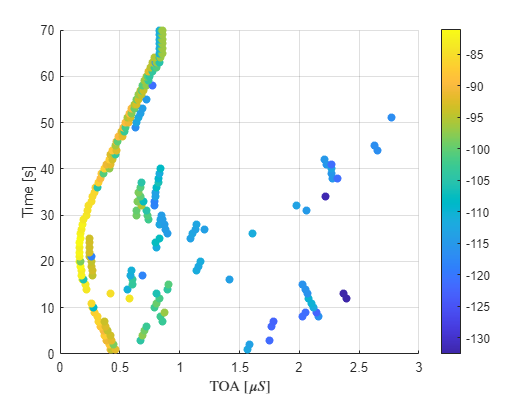

TxID = 1;
RxID = 4;
toa_scale_factor=1e6;

figure
tau =[];
for snapshotIdx = 1:size(chMatrix,3)
    scatter( cell2mat(chMatrix_hat{TxID,RxID,snapshotIdx}(:,1)) * toa_scale_factor, ...
             ones(size(chMatrix_hat{TxID,RxID,snapshotIdx}(:,1))) * parameters.Ts * snapshotIdx, [], ...
             mag2db(abs(cell2mat(chMatrix_hat{TxID,RxID,snapshotIdx}(:,2)))) , 'filled');
    hold on
end
colorbar
grid on
xlabel('TOA [$\mu S$]','Interpreter','latex');
ylabel('Time [s]')

% Wrap the metadata required for Colosseum scenario generator toolchain
origin.lat = parameters.origin(1);
origin.long = parameters.origin(2);

NodesName = parameters.nodes.names;

chMatrix = chMatrix_hat;
plMatrix = plMatrix_hat;

% save the required variable for Colosseum multi-tap toolchain
save("RFscenario.mat","chMatrix","plMatrix", ...
     "NodesName","coordinates","Time","origin");